T=readtimetable("seclog.xlsx")

T = 13381×2 timetable
            Time            Var1               Var2            
    ____________________    ____    ___________________________

    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec-2023 21:50:35    5379    {'User Account Management'}
    19-Dec

T.Properties.DimensionNames(1,1) = "datetime";
T.Properties.VariableNames(1) = "EventCode";
T.Properties.VariableNames(2) = "EventCategory";
summary(T)

RowTimes:

    datetime: 13381×1 datetime
        Values:
            Min         16-Dec-2023 23:29:32 
            Median      18-Dec-2023 15:43:48 
            Max         19-Dec-2023 21:50:35 

Variables:

    EventCode: 13381×1 double

        Values:

            Min         1100  
            Median      5379  
            Max         5382  

    EventCategory: 13381×1 cell array of character vectors



T.hr_of_day = hour(T.datetime)

T = 13381×3 timetable
          datetime          EventCode           EventCategory           hr_of_day
    ____________________    _________    ___________________________    _________

    19-Dec-2023 21:50:35      5379       {'User Account Management'}       21    
    19-Dec-2023 21:50:35      5379       {'User Account Management'}       21    
    19-Dec-2023 21:50:35      5379       {'User Account Management'}       21    
    19-Dec-2023 21:50:35      5379       {'User Account Management'}       21    
    19-Dec-2023 21:50:35      5379       {'User Account Management'}       21    
    19-Dec-2023 21:50:35      5379       {'User Account Management'}       21    
    19-Dec-2023 21:50:35      5379       {'User Account Management

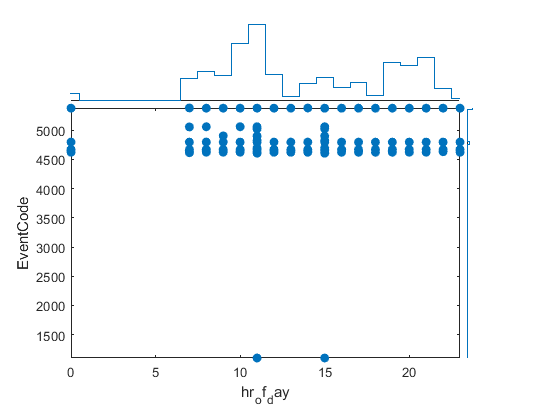

scatterhistogram(T,"hr_of_day","EventCode" )

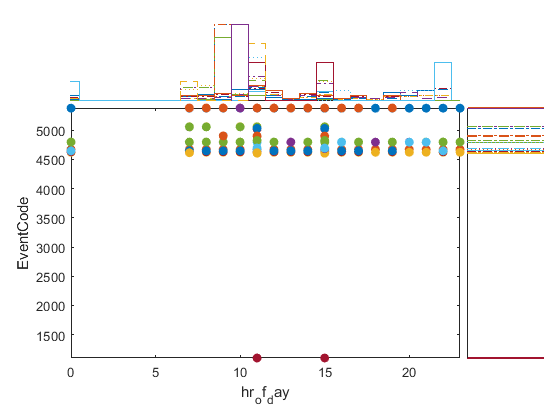

scatterhistogram(T,"hr_of_day","EventCode",'GroupVariable',"EventCode" )

H=groupsummary(T,["hr_of_day","EventCode"], 'IncludeEmptyGroups', true)

H = 450×3 table
    hr_of_day    EventCode    GroupCount
    _________    _________    __________

        0          1100            0    
        0          4608            0    
        0          4616            0    
        0          4624           24    
        0          4634            3    
        0          4647            2    
        0          4648            4    
        0          4672           22    
        0          4688            0    
        0          4696            0    
        0          4797            0    
        0          4798           19    
        0          4799            2    
        0          4826            0    
        0          4902            0    
        0          4904            0    


H1=groupsummary(T,"hr_of_day")

H1 = 18×2 table
    hr_of_day    GroupCount
    _________    __________

        0            206   
        7            656   
        8            864   
        9            732   
       10           1674   
       11           2215   
       12            767   
       13            135   
       14            516   
       15            686   
       16            382   
       17            541   
       18            161   
       19           1109   
       20           1039   
       21           1274   


%bar(H1.hr_of_day, H1.GroupCount)
H2 = groupsummary(H, "hr_of_day", @(x) { x' }, ["EventCode", "GroupCount"])

H2 = 18×4 table
    hr_of_day    GroupCount                                                             fun1_EventCode                                                                                       fun1_GroupCount                          
    _________    __________    ________________________________________________________________________________________________________________________________    ___________________________________________________________________

        0            25        {[1100 4608 4616 4624 4634 4647 4648 4672 4688 4696 4797 4798 4799 4826 4902 4904 4905 5024 5033 5058 5059 5061 5379 5381 5382]}    {[         0 0 0 24 3 2 4 22 0 0 0 19 2 0 0 0 0 0 0 0 0 0 130 0 0]}
        7            25        {[1100 4608 4616 4624 4634 4647 4648 4672 4688 4696 4797 4798 4799 4826 4902 4904 4905 5024 5033 5058 5059 5061 5379 5381 5

hrs = H2.hr_of_day;
counts = cell2mat(H2.fun1_GroupCount(:))

counts =            0           0           0          24           3           2           4          22           0           0           0          19           2           0           0           0           0           0           0           0           0           0         130           0           0
           0           0           1          31           4           0           4          27           0           0           0         123           2           0           0           0           0           0           0           4           2           3         453           0           2
           0           0           0          27           4           0           4          23           0           0           0         127           4           0           0           0           0           0           0           4           2           4         663           0           2
           0           0           0          49           6           0           3    

codes = H2.fun1_EventCode{1}

codes =         1100        4608        4616        4624        4634        4647        4648        4672        4688        4696        4797        4798        4799        4826        4902        4904        4905        5024        5033        5058        5059        5061        5379        5381        5382


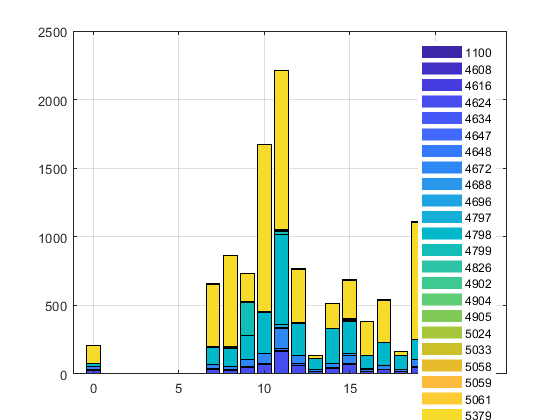

b = bar(hrs, counts, 'stacked','FaceColor','flat');
for k = 1:size(counts,2)
b(k).CData = k;
end
grid on
legend(num2cell(string(codes)))